algorithm in reverse procedure along cc rule without any modify

If the arrangement is in the expression Ax=b, then the input is the coefficient matrix A_=[A|b]

% A_=[-1 0 -1
%     0 -1 -1
%     1 0 3
%     0 1 3
%     -1 1 -3]

A_ =     -1     0    -1
     0    -1    -1
     1     0     3
     0     1     3
    -1     1    -3


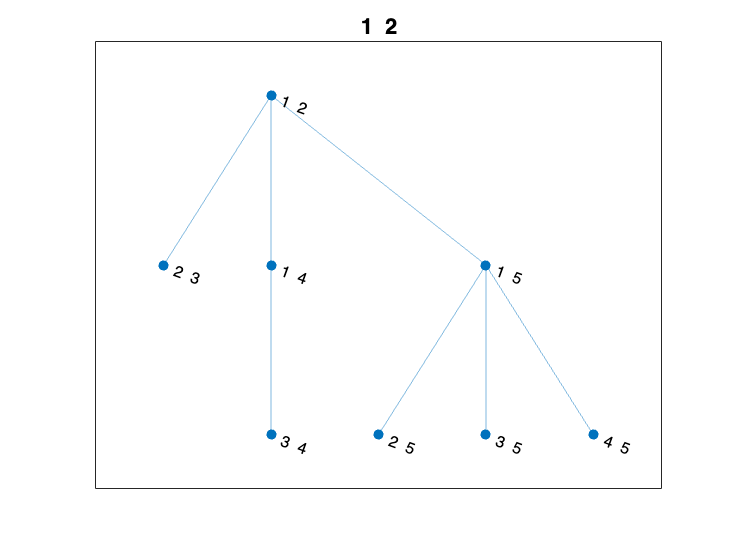

tic

[B,N,A]=dictionary_noobj(A_);
[reversezeros,vertex]=reverse(B,N,A);

plot(reversezeros,'Layout','layered');
title(num2str(N(2:end)))


result=comput(vertex,A_)

result =      1    -2
     1     1
     1     3
     3     0
     3     1
     3     3
     4     1
     6     3



toc

Elapsed time is 0.459617 seconds.


This function construct the initial dictionary from the given coefficient matrix of system, output the basis B, co-basis N, coefficient matrix of dictionary A

function [B,N,A]=dictionary_noobj(A_)
[n,d]=size(A_);d=d-1;

A0=A_(:,1:end-1);b=A_(:,end);

A_N=[];N=[0];
[n,d]=size(A0);

for i=1:n
    if rank(A0(1:i,:))>rank(A0(1:i-1,:))
        A_N=[A_N;A0(i,:)];
        N=[N,i];
        if rank(A_N)==d;
            break
        end 
    end
end

B=[setdiff(1:n,N(2:end))];

A=[[b(B(1:end)),zeros(n-d,d)]-A0(B(1:end),:)*inv(A_N)*[b(N(2:end)),-eye(d)]];
end

This function based on input dictionary with set B,N,A do reverse along Criss-Cross rule, and output :

1, "vertex" each row is one set N passing lex-min test

2, "reversezeros" represent a graph of spanning tree rooted at input N

function [reversezeros,vertex]=reverse(B,N,A)
s={};t={};
j=2;i=1;
layer=0;
d=length(N)-1;

vertex=[];
lexmin=lexicography(B,N,A);
if lexmin==1
    vertex=[vertex;N(2:end)];
end

while j<=length(N)+1
    if j<=length(N) && layer<d
        reversezero=testzeroreserse(B,N,A,i,j);
        if reversezero==1
            if layer<d-1
                s=[s,num2str(N(2:end))];
                [B,N,A]=pivotrowcolumn(B,N,A,i,j);
                t=[t,num2str(N(2:end))];
                lexmin=lexicography(B,N,A);
                if lexmin==1
                    vertex=[vertex;N(2:end)];
                end
                layer=layer+1;
                j=2;
                i=1;
            else
                s=[s,num2str(N(2:end))];
                [tempB,tempN,tempA]=pivotrowcolumn(B,N,A,i,j);
                t=[t,num2str(tempN(2:end))];
                lexmin=lexicography(tempB,tempN,tempA);
                if lexmin==1
                    vertex=[vertex;tempN(2:end)];
                end
                i=i+1;
                if i==length(B)+1
                    i=1;j=j+1;
                end
            end
        else
            i=i+1;
            if i==length(B)+1
                i=1;j=j+1;
            end
        end
    else
        [i,j]=selectzero(B,N,A);
        if (isempty(i)==0 && isempty(j)==0)
            Bi=B(i);Nj=N(j);
            [B,N,A]=pivotrowcolumn(B,N,A,i,j);
            layer=layer-1;
            i=find(B==Nj);j=find(N==Bi);
            i=i+1;
            if i==length(B)+1
                i=1;j=j+1;
            end
        else
            reversezeros=graph(s,t);
            break
        end
    end
end
end

This function used to do pivot from input B,N,A and fixed pair B(i),N(j) as the i,j-th entry in A, output represent dictionary after update

function [B,N,A]=pivotrowcolumn(B,N,A,i,j)
C=zeros(size(A));
for l=1:length(B) %compute remainders in the pivot
    C(l,:)=A(l,:)-A(i,:)*A(l,j)/A(i,j);
end
C(i,:)=-A(i,:)/A(i,j); % compute the row in the pivot
C(:,j)=A(:,j)/A(i,j);C(i,j)=1/A(i,j); % compute the column the the fixed entry in pivot
N0=N;B0=B;
B(i)=N0(j);[B,I]=sort(B); % sort new B
N(j)=B0(i);[N,J]=sort(N); % sort new N
C=C(:,J);C=C(I,:);A=C; % permute the row and column of C in correspondence way
end

This function gives method to apply the Zero rule and give the position of this rule fixed as the i,j-th entery

function [i,j]=selectzero(B,N,A)
i=[];j=[];
for j=2:length(A(end,:))
    temp=find(A(find(B<N(j)),j)~=0);
    if isempty(temp)==0
        i=min(temp);
        break
    end
end
end

This function gives method to test if i,j-th entery is a pair of valid Zero rule reverse, if yes, reversedb=1, otherwise =0

function reversezero=testzeroreserse(B,N,A,i,j)
reversezero=0;
if N(j)<B(i) && A(i,j)~=0
    B0=find(B<N(j));B0(B0==i)=[];
    if all(A(B0,j)==0)
        N0=find(N<B(i));N0(1)=[];N0(N0==j)=[];
        if isempty(N0)==1
            reversezero=1;
        else
            temp=[];
            for l=N0
                if all(A(B<N(l),l)==0)
                    if l<=j
                        temp=[temp,1];
                    else
                        if A(i,l)==0
                            temp=[temp,1];
                        end
                    end 
                end
            end
            if length(temp)==length(N0)
                reversezero=1;
            end
        end
    end
end
end

This function gives method to test if the current dictionary pass the lex-min test, if yes, lexmin=1, otherwise =0

function lexmin=lexicography(B,N,A)
B0=B(find(A(:,1)==0));
lexmin=1;
if isempty(B0)==1
    lexmin=1;
else
    for i=length(B0):-1:1
        N0=find(N(2:end)<B0(i))+1;
        if isempty(N0)==0
            if any(A(find(B==B0(i)),N0)~=0)==1
                lexmin=0;
                break
            end
        else
            break
        end
    end
end
end

This function based on the given coefficient matrix of arrangement and obtained set of indexes N to comput all vertex after enumeration

function result=comput(result_dic,A_)
[ver,~]=size(result_dic);[~,n_]=size(A_);A_=[A_;-eye(n_)];A_=A_(1:end-1,:);
vertex=[];
for i=1:ver
    vert=inv(A_(result_dic(i,:),1:end-1))*A_(result_dic(i,:),end);
    vertex=[vertex;transpose(vert)];
end
result=sortrows(vertex);
end